# Lab - Optimization

**Topics: **fminbnd, fminsearch

## 1D Optimization

clear, clc

### Set up problem

As electric current moves through a wire heat generated by resistance is conducted through a layer of insulation and then convected to the surrounding air. The steady-state temperature of the wire can be computed as: $T=T_{\textrm{air}} +\frac{q}{2\pi }\left\lbrack \frac{1}{k}\ln \left(\frac{r_w +r_i }{r_w }\right)+\frac{1}{h}\;\frac{1}{r_w +r_i }\right\rbrack$

Determine the thickness of insulation $r_i$(m) that minimizes the wire’s temperature given the following parameters: $q=75$ W/m, $r_w =6$mm, $k=0\ldotp 17$W/(m K), $h=12$W/(${\mathrm{m}}^2$ K), and $T_{\textrm{air}} =293$K.

q =75;
rw = 6;
k = .17;
h = 12;
tAir = 293;


mmtometer = 1/1000;
rWmeter = rw*mmtometer;
T = @(rI) tAir+q/(2*pi)*(1/k*log((rWmeter+rI)/rWmeter)+ 1/h*1./(rWmeter+rI));

### Plot to see what is reasonable

figure(1)
fplot(T,[rWmeter 2*rWmeter])
ylabel('wire temp [K]')
xlabel('insulation thickness [m]')

### Find the radius of the wire insulation that minimizes the wire temperature

[rimin, tMin] = fminbnd(T,rWmeter,2*rWmeter)

rimin = 0.0082

tMin = 423.5398

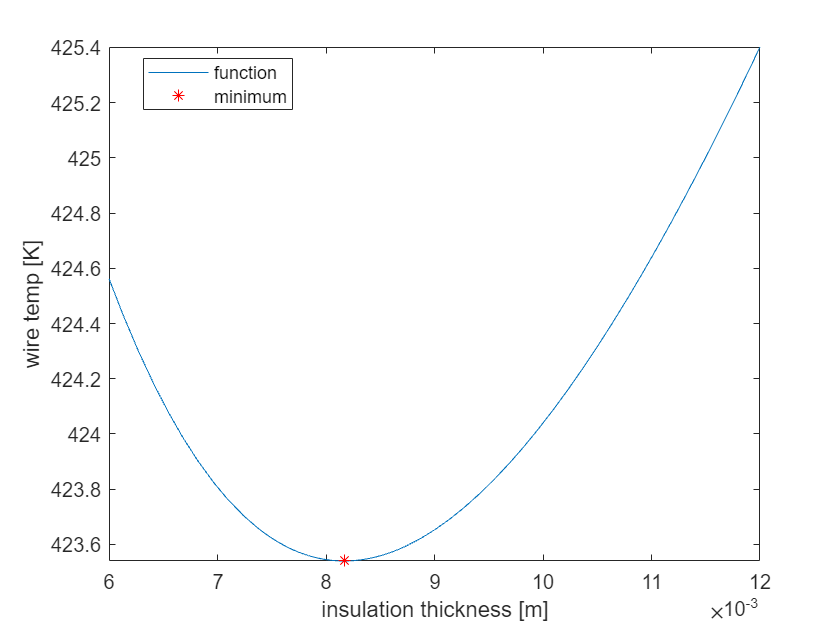

hold on;
plot(rimin,tMin,'r*')
legend('function','minimum', 'location','best')

### What is the total thickness of the wire and insulation in mm to three decimals?

rtotal = rimin+rWmeter;
fprintf('the total thickness is %5.3f mm',rtotal)

the total thickness is 0.014 mm

## 2D Optimization

clear, clc, clf

The head of a groundwater aquifer is described in Cartesian coordinates by: $h\left(x,y\right)=\frac{1}{1+x^2 +y^2 +x+\mathrm{xy}}$

Find the head maximum between $-4\le x\le 2$ and $-2\le y\le 3$

### Set up the data

x = linspace(-4,2);
y = linspace(-2,3);
h = @(x,y) 1./(1+x.^2+y.^2+x+x.*y);

### Plot to see what's reasonable

[X,Y] = meshgrid(x,y);
z = h(X,Y);
surf(X,Y,z)
xlabel('x pos [m]')
ylabel('y pos [m]')
zlabel('z pos [m]')

### Find the maximum

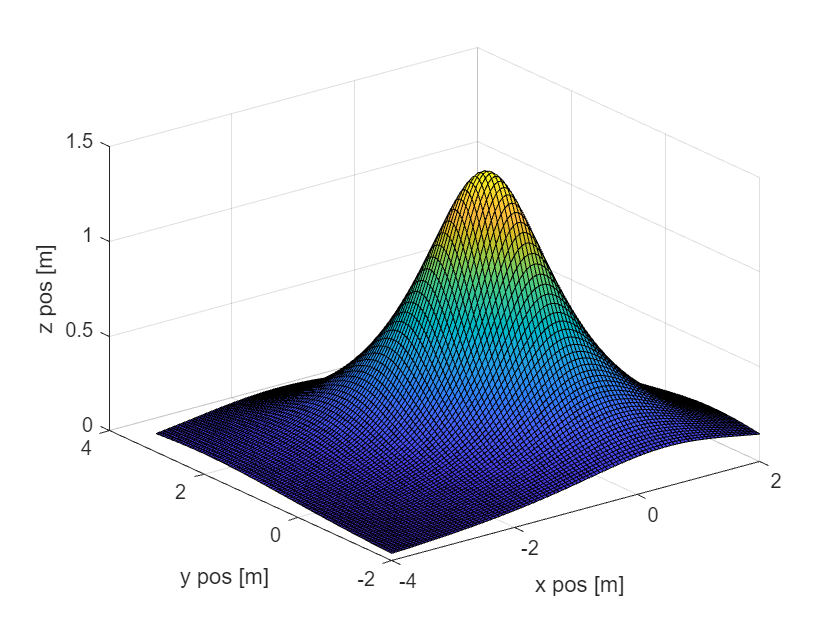

g = @(p) -h(p(1),p(2));
[q,fmin] = fminsearch(g, [0 0]);
hold on;
plot3(q(1),q(2),-fmin)

legend('head surface','maximum')